## Mars TD

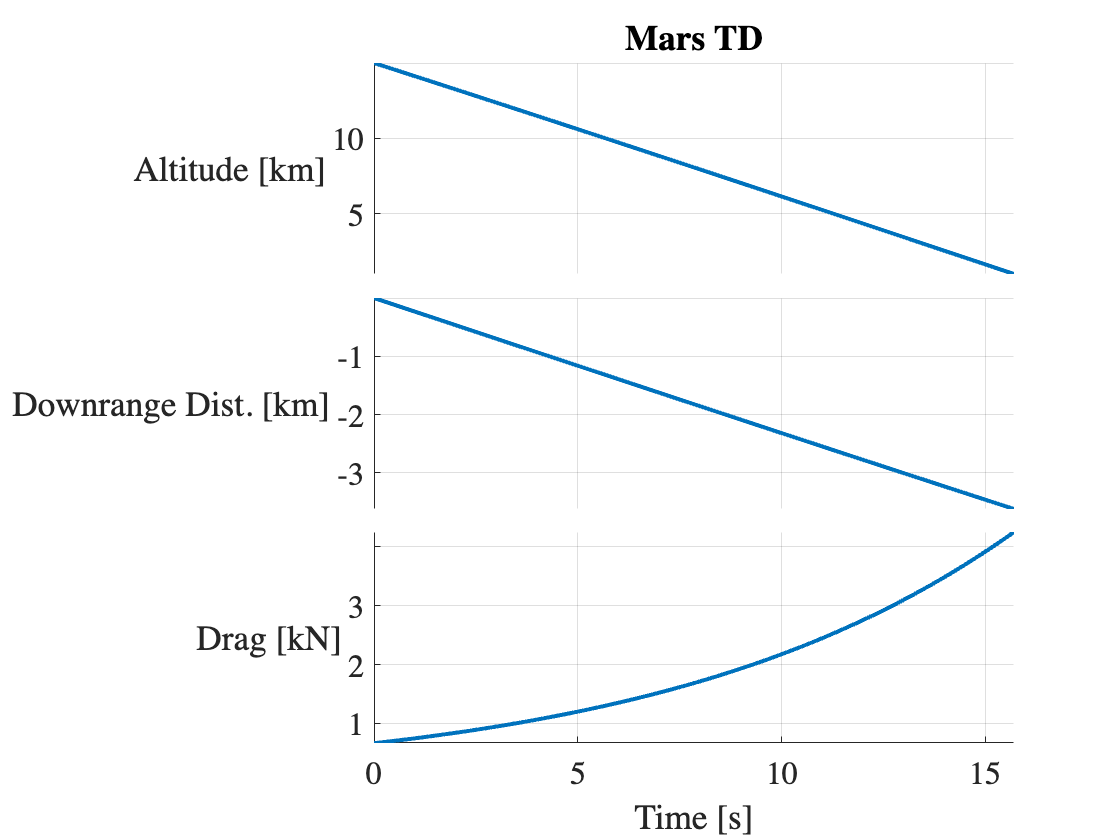

D_EV = 4.5; %m
CD_EV = 1.65;
m = 1200; %kg
n = 1;
eta = 1;
D_P = 21.5; %m
g = 3.74; %m/s^2
rho_0 = 0.057; %kg/m^3
A = 1.28e-4; %1/m
h_i = 15e3; %m
h_f = 1e3; %m
v_i = -900; %m/s
theta = 15; %deg
CD_P = 0.58;

s=0;
h = h_i;
vs = v_i*sind(theta);
vh = v_i*cosd(theta);

t = 0; %s
deltat = 0.05; %s
X1 = t;
Y1 = [h s 1/2*rho_0*exp(-A*h)*(vs^2 + vh^2)/m*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2)];
while h>h_f
    F_D = 1/2*rho_0*exp(-A*h)*(vs^2 + vh^2)/m*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2);
    F_g = m*g;
    as = 1/m*F_D*sind(theta);
    ah = 1/m*(F_D*cosd(theta) - F_g);
    vs = vs + as*deltat;
    vh = vh + ah*deltat;
    h = h + vh*deltat;
    s = s + vs*deltat;
    t = t + deltat;
    X1 = [X1;t];
    Y1 = [Y1;[h s F_D]];
end
X1 = X1(1:end-1,:);
Y1 = Y1(1:end-1,:);
figure(101);
stackedplot(X1,Y1/1000,'DisplayLabels',["Altitude [km]","Downrange Dist. [km]","Drag [kN]"],'LineWidth',2)
set(gca,'FontSize',16,'FontName','Calibri')
grid on
xlabel("Time [s]")
title("Mars TD")

C_x = 1.3;
F_i = C_x*Y1(1,3)*m;
F_f = Y1(end,3)*m;
fprintf("Initial Parachute Load: %.2f kN\nFinal Parachute Load: %.2f kN",F_i/1000,F_f/1000)

Initial Parachute Load: 1041.91 kN
Final Parachute Load: 5104.82 kN

h = 1e3; %m
v_t = sqrt(m*g/(rho_0*exp(-A*h)*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2)));
fprintf("Terminal Velocity: %.2f m/s",v_t)

Terminal Velocity: 19.44 m/s

## Venus TD

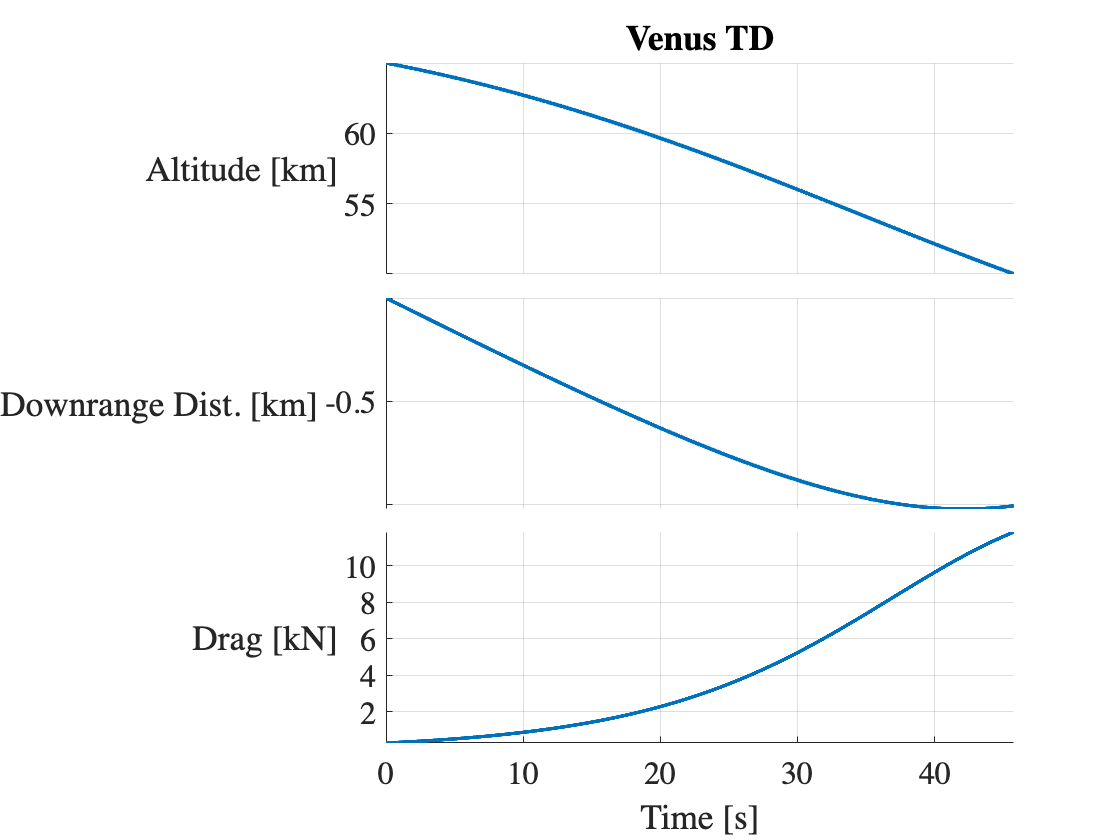

D_EV = 1.5; %m
CD_EV = 0.9;
n = 1;
eta = 1;
m = 800; %kg
D_P = 9; %m
g = 8.87; %m/s^2
rho_0 = 16.02; %kg/m^3
A = 1.61e-4; %1/m
h_i = 65e3; %m
h_f = 50e3; %m
v_i = -190; %m/s
theta = 10; %deg
CD_P = 0.55;

s=0;
h = h_i;
vs = v_i*sind(theta);
vh = v_i*cosd(theta);

t = 0; %s
deltat = 0.005; %s
X2 = t;
Y2 = [h s 1/2*rho_0*exp(-A*h)*(vs^2 + vh^2)*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2)];
while h>h_f
    F_D = 1/2*rho_0*exp(-A*h)*(vs^2 + vh^2)*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2);
    F_g = m*g;
    as = 1/m*F_D*sind(theta);
    ah = 1/m*(F_D*cosd(theta) - F_g);
    vs = vs + as*deltat;
    vh = vh + ah*deltat;
    h = h + vh*deltat;
    s = s + vs*deltat;
    t = t + deltat;
    X2 = [X2;t];
    Y2 = [Y2;[h s F_D]];
end

figure(102);
stackedplot(X2,Y2/1000,'DisplayLabels',["Altitude [km]","Downrange Dist. [km]","Drag [kN]"],'LineWidth',2)
set(gca,'FontSize',16,'FontName','Calibri')
grid on
xlabel("Time [s]")
title("Venus TD")

C_x = 1.05;
F_i = C_x*Y2(1,3);
F_f = Y2(end,3);
fprintf("Initial Parachute Load: %.2f kN\nFinal Parachute Load: %.2f kN",F_i/1000,F_f/1000)

Initial Parachute Load: 0.32 kN
Final Parachute Load: 11.84 kN

h = 1e3; %m
v_t = sqrt(m*g/(rho_0*exp(-A*h)*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2)));
fprintf("Terminal Velocity: %.2f m/s",v_t)

Terminal Velocity: 3.77 m/s

## Earth TD

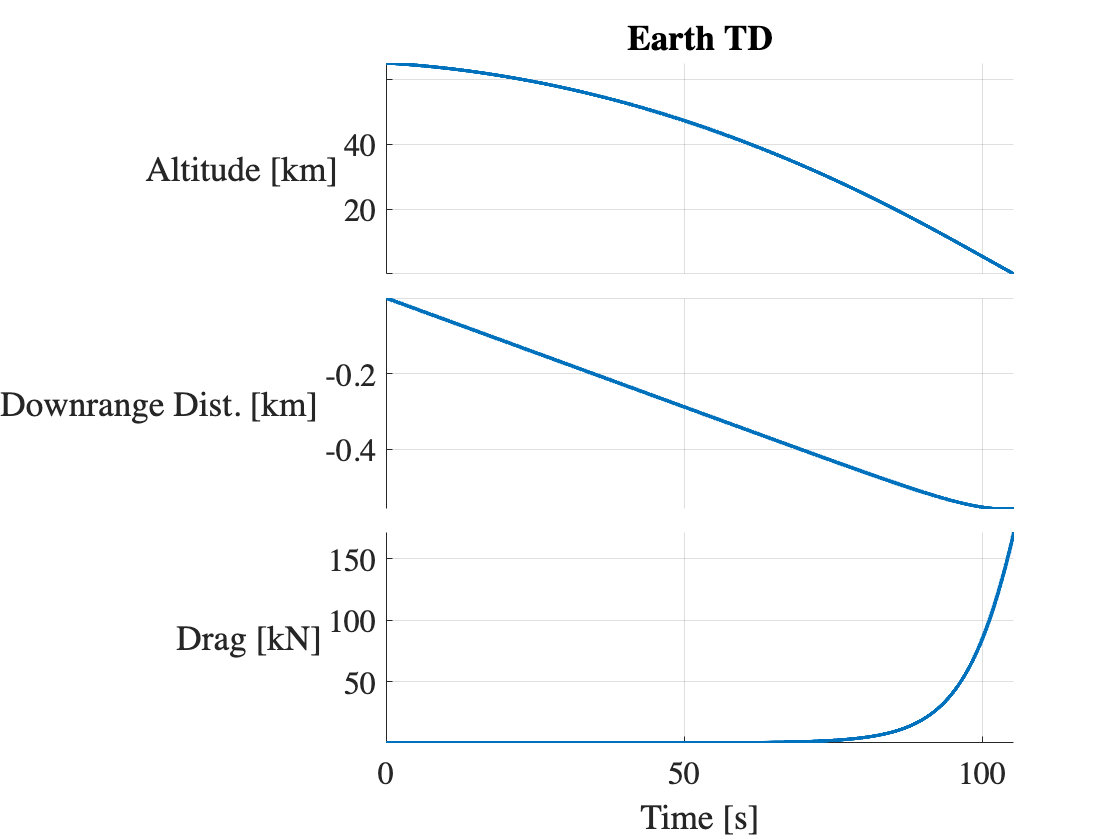

D_EV = 5; %m
CD_EV = 1.4;
n = 3;
eta = 0.95;
m = 9000; %kg
D_P = 35; %m
g = 9.81; %m/s^2
rho_0 = 1.225; %kg/m^3
A = 1.38e-4; %1/m
h_i = 65e3; %m
h_f = 0e3; %m
v_i = -110; %m/s
theta = 3; %deg
CD_P = 0.9;

s=0;
h = h_i;
vs = v_i*sind(theta);
vh = v_i*cosd(theta);

t = 0; %s
deltat = 0.005; %s
X3 = t;
Y3 = [h s 1/2*rho_0*exp(-A*h)*(vs^2 + vh^2)/m*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2)];
while h>h_f
    F_D = 1/2*rho_0*exp(-A*h)*(vs^2 + vh^2)/m*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2);
    F_g = m*g;
    as = 1/m*F_D*sind(theta);
    ah = 1/m*(F_D*cosd(theta) - F_g);
    vs = vs + as*deltat;
    vh = vh + ah*deltat;
    h = h + vh*deltat;
    s = s + vs*deltat;
    t = t + deltat;
    X3 = [X3;t];
    Y3 = [Y3;[h s F_D]];
end

figure(103);
stackedplot(X3,Y3/1000,'DisplayLabels',["Altitude [km]","Downrange Dist. [km]","Drag [kN]"],'LineWidth',2)
set(gca,'FontSize',16,'FontName','Calibri')
grid on
xlabel("Time [s]")
title("Earth TD")

C_x = 1.1;
F_i = C_x*Y3(1,3);
F_f = Y3(end,3);
fprintf("Initial Parachute Load: %.2f N\nFinal Parachute Load: %.2f kN",F_i,F_f/1000)

Initial Parachute Load: 0.29 N
Final Parachute Load: 171.71 kN

h = 1e3; %m
v_t = sqrt(m*g/(rho_0*exp(-A*h)*pi/4*(CD_EV*D_EV^2 + n*eta*CD_P*D_P^2)));
fprintf("Terminal Velocity: %.2f m/s",v_t)

Terminal Velocity: 5.76 m/s